% Find all real and complex roots of the polynomial
% f(x) = 2x^4 + 3x^3 - 5x^2 + 2x + 1
% [a4 a3 a2 a1 a0] = [2 3 -5 2 1]
% MM1 and MM2 / Newton's method and compare to MM2
%                 (the same initial points)

clear
syms x;
p = [2 3 -5 2 1];
r = roots(p)

r =   -2.5869 + 0.0000i
   0.6829 + 0.4759i
   0.6829 - 0.4759i
  -0.2790 + 0.0000i


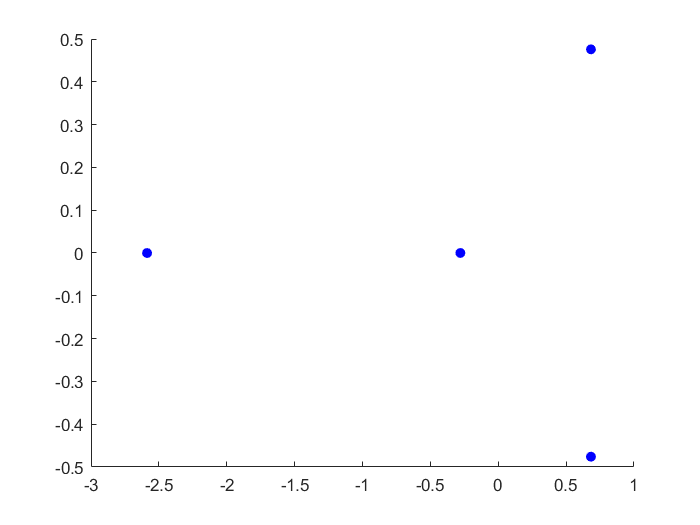

scatter(real(r),imag(r),'filled','blue')

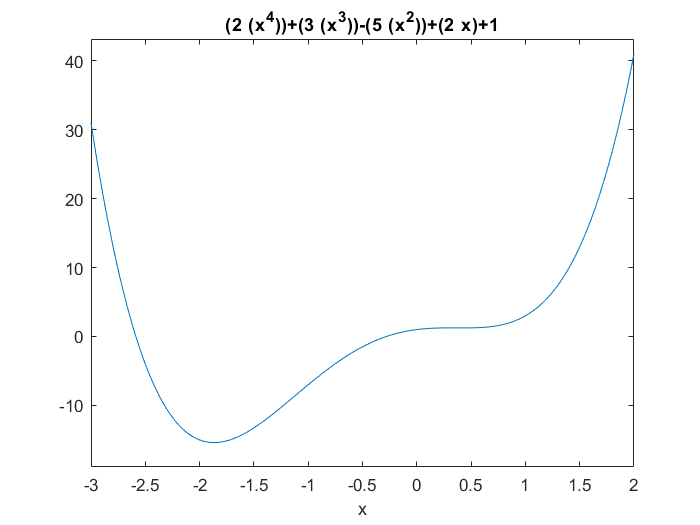

ezplot('(2*(x^4))+(3*(x^3))-(5*(x^2))+(2*x)+1',[-3 2])

f = @(x) 2*x^4 + 3*x^3 - 5*x^2 + 2*x + 1;
df = @(x) 8*x^3 + 9*x^2 - 10*x + 2;
%g = diff(df(x))
ddf = @(x) 24*x^2 + 18*x - 10;

x1 = -10.0;
x2 = -1.5;
x3 = 9.0;
disp("****************MM1******************");

****************MM1******************


X: 
   -2.5869

Error: 
   2.1095e-10

Iterations: 
    11



x_vec =          0   -3.0225   -2.5488   -2.5894   -2.5868   -2.5869   -2.5869   -2.5869   -2.5869   -2.5869   -2.5869


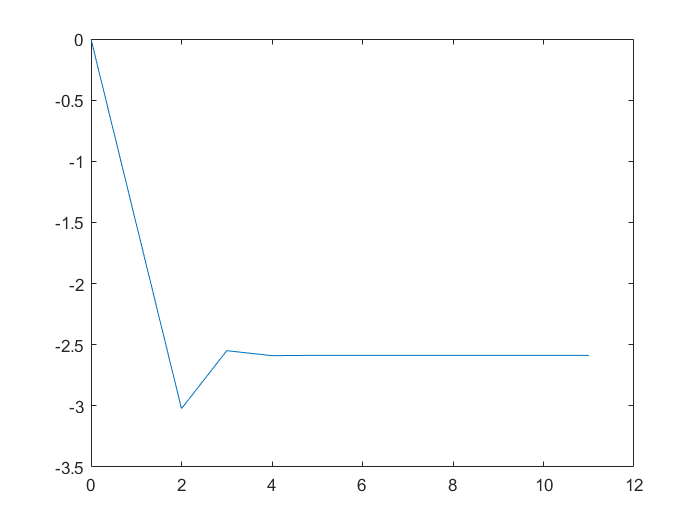

MM1(-2.9, -3.1, -40, f);% showing real root

X: 
   -0.2790

Error: 
   3.6716e-10

Iterations: 
     7



x_vec =          0   -0.0000   -0.2743   -0.2790   -0.2790   -0.2790   -0.2790


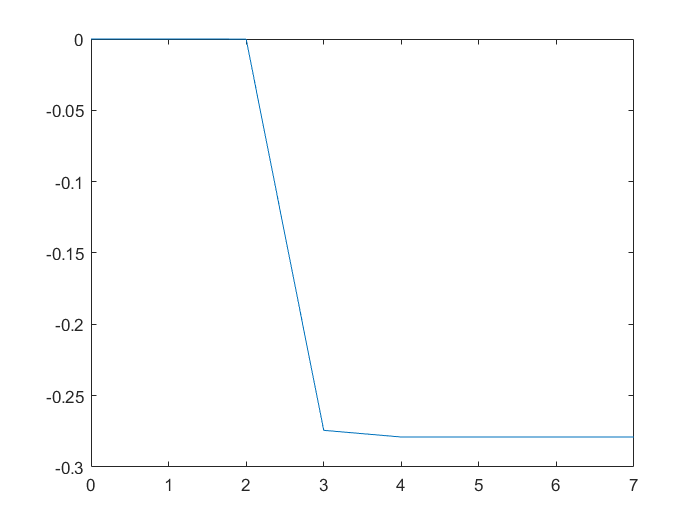

MM1(0, -1, 100, f);  % showing real root

X: 
   0.6829 + 0.4759i

Error: 
   7.4718e-10

Iterations: 
    20



x_vec =    0.0000 + 0.0000i   0.8043 + 0.0344i   0.5914 + 0.3918i   0.6489 + 0.4978i   0.6878 + 0.4875i   0.6867 + 0.4751i   0.6829 + 0.4747i   0.6826 + 0.4758i   0.6829 + 0.4760i   0.6830 + 0.4759i   0.6830 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i


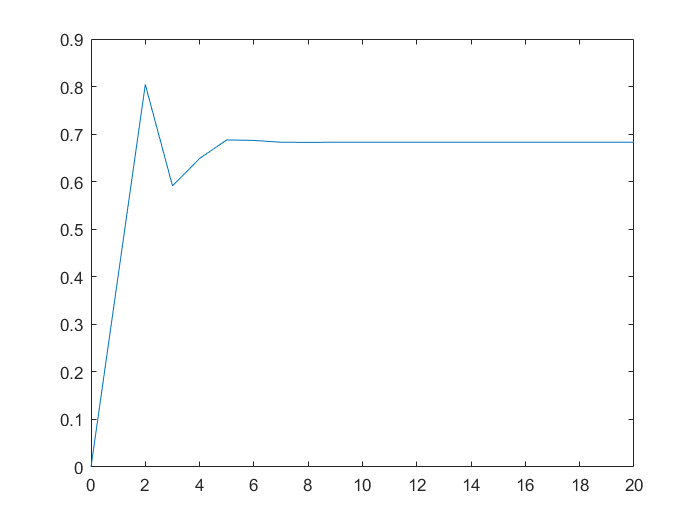

MM1(0.7, 0.8, 10+10i, f); % showing complex root

X: 
   0.6829 - 0.4759i

Error: 
   7.4718e-10

Iterations: 
    20



x_vec =    0.0000 + 0.0000i   0.8043 - 0.0344i   0.5914 - 0.3918i   0.6489 - 0.4978i   0.6878 - 0.4875i   0.6867 - 0.4751i   0.6829 - 0.4747i   0.6826 - 0.4758i   0.6829 - 0.4760i   0.6830 - 0.4759i   0.6830 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i


MM1(0.7, 0.8, 10-10i, f); % showing complex root

disp("****************MM2******************");

****************MM2******************


** MM2 **
X: 
   -2.5869

Error: 
   3.0198e-14

Iterations: 
    10



x_vec =          0   -6.8728   -4.8390   -3.5725   -2.8806   -2.6238   -2.5876   -2.5869   -2.5869   -2.5869


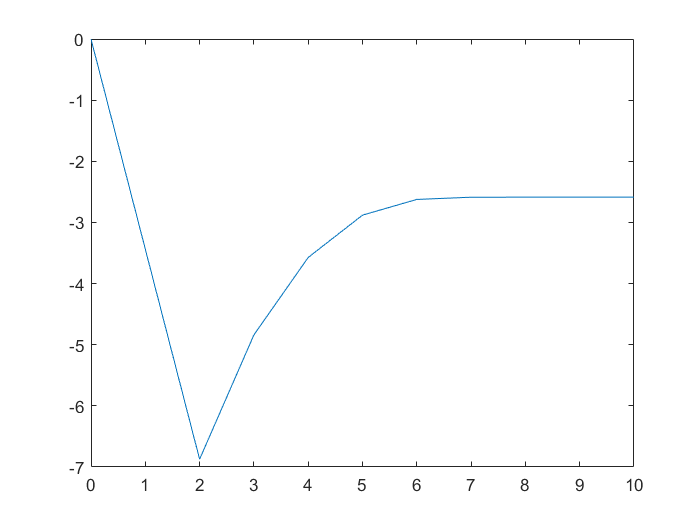

MM2(x1, f, df, ddf); % showing real root

** MM2 **
X: 
   -0.2790

Error: 
   1.3090e-13

Iterations: 
     7



x_vec =          0   -0.5677   -0.3171   -0.2798   -0.2790   -0.2790   -0.2790


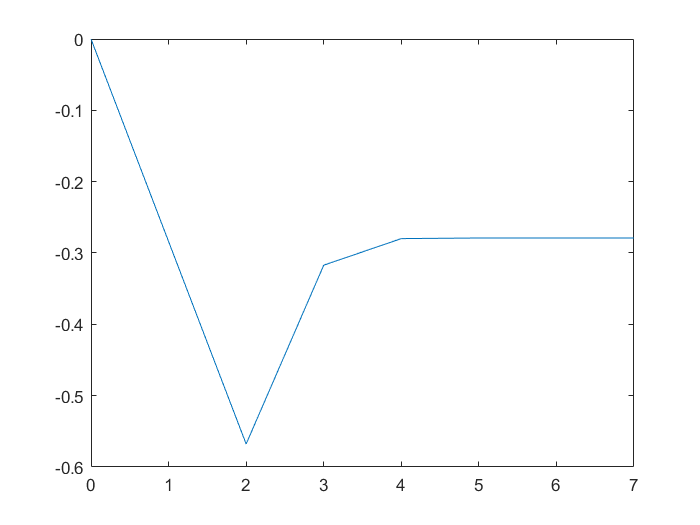

MM2(x2, f, df, ddf); % showing real root

** MM2 **
X: 
   0.6829 + 0.4759i

Error: 
   8.8818e-16

Iterations: 
    14



x_vec =    0.0000 + 0.0000i   5.9332 + 0.0000i   3.9101 + 0.0000i   2.5853 + 0.0000i   1.7225 + 0.0000i   1.1451 + 0.0000i   0.6087 + 0.0000i   0.3951 + 0.6992i   0.5832 + 0.4205i   0.6968 + 0.4761i   0.6831 + 0.4757i   0.6829 + 0.4759i   0.6829 + 0.4759i   0.6829 + 0.4759i


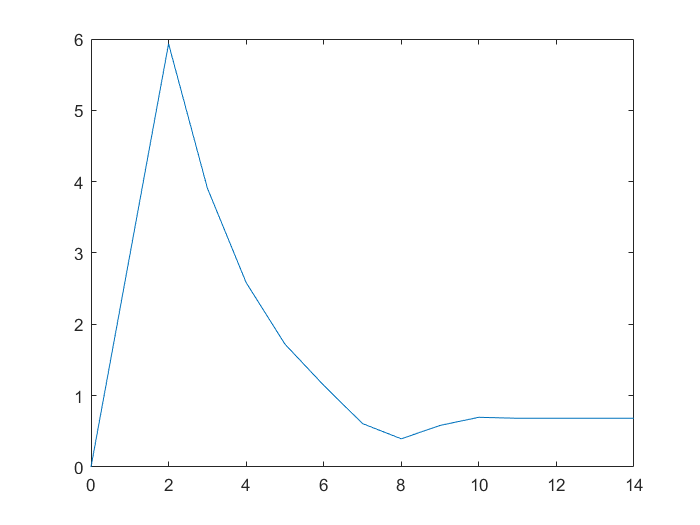

MM2(x3, f, df, ddf); % showing complex root

** MM2 **
X: 
   0.6829 - 0.4759i

Error: 
   8.8818e-16

Iterations: 
    14



x_vec =    0.0000 + 0.0000i   5.9332 + 0.0000i   3.9101 + 0.0000i   2.5853 + 0.0000i   1.7225 + 0.0000i   1.1451 + 0.0000i   0.6087 + 0.0000i   0.3951 - 0.6992i   0.5832 - 0.4205i   0.6968 - 0.4761i   0.6831 - 0.4757i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i


MM2_(x3, f, df, ddf); % showing complex root

disp("****************NEW******************");

****************NEW******************


**NEWTON's METHOD**
X: 
   -2.5869

Error: 
   4.0856e-14

Iterations: 
    11

Plot Iterations/Solution


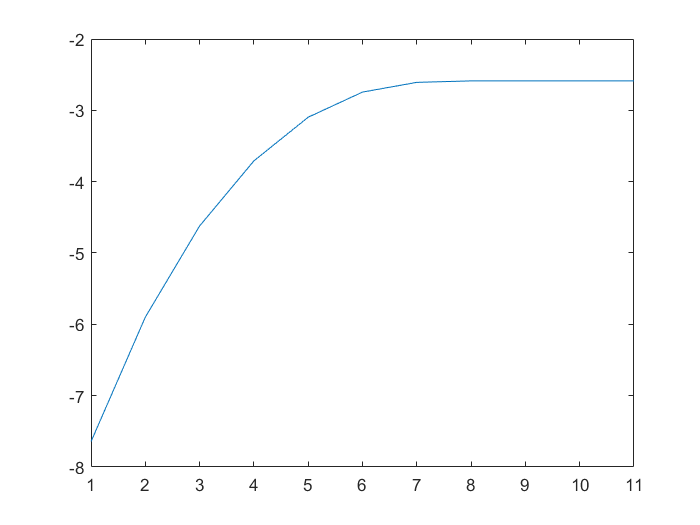

x_vec =    -7.6449   -5.8992   -4.6206   -3.7083   -3.0962   -2.7440   -2.6079   -2.5874   -2.5869   -2.5869   -2.5869


Newtons_fun(x1, f, df); %showing only real root

**NEWTON's METHOD**
X: 
   -0.2790

Error: 
   5.5511e-17

Iterations: 
     6

Plot Iterations/Solution


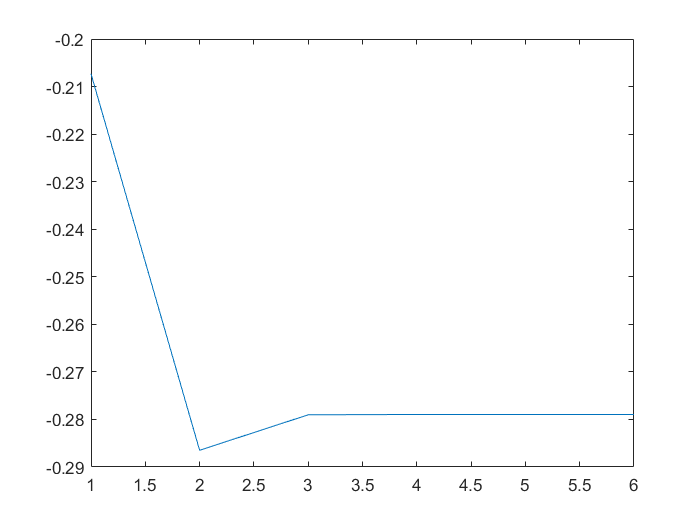

x_vec =    -0.2073   -0.2865   -0.2790   -0.2790   -0.2790   -0.2790


Newtons_fun(x2, f, df); %showing only real root

disp("Newton for x3 value / prove that "); 

Newton for x3 value / prove that 


 disp("it cannot calc complex root: ");

it cannot calc complex root: 


**NEWTON's METHOD**
X: 
    2.6392

Error: 
    0.9051

Iterations: 
    31

Plot Iterations/Solution


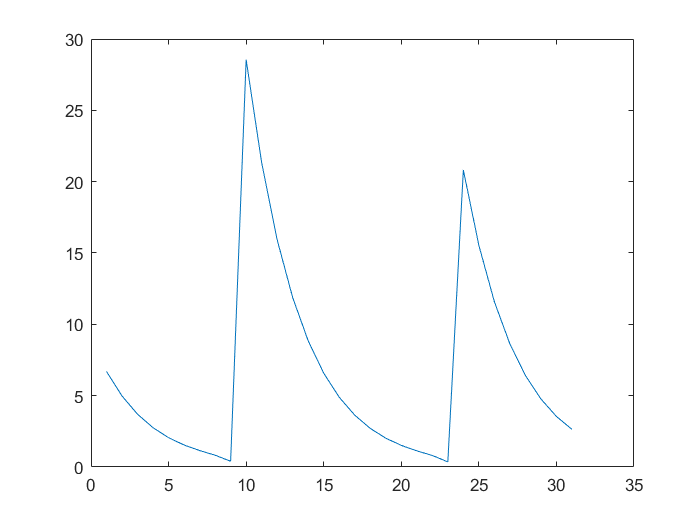

x_vec =     6.6946    4.9756    3.6982    2.7527    2.0558    1.5415    1.1529    0.8269    0.4035   28.5536   21.3352   15.9257   11.8740    8.8421    6.5767    4.8879    3.6331    2.7047    2.0205    1.5152    1.1324    0.8072    0.3614   20.8212   15.5405   11.5856    8.6265    6.4158    4.7682    3.5443    2.6392


Newtons_fun(x3, f, df); %Trying to get complex

disp("****************LAG******************");

****************LAG******************


** Laguerre **
X: 
   -2.5869

Error: 
   1.2279e-12

Iterations: 
    10

Plot Iterations/Solution


x_vec =          0   -6.9904   -4.9887   -3.7034   -2.9595   -2.6457   -2.5887   -2.5869   -2.5869   -2.5869


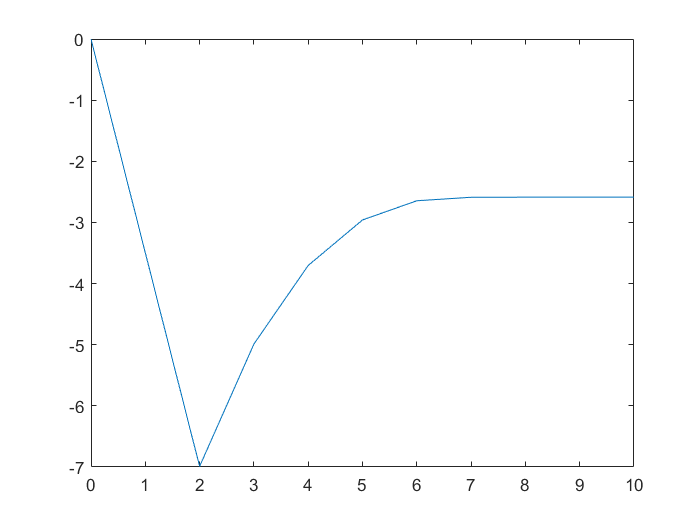

% Task 3
Laguerre(x1, f, df, ddf); % showing real root

** Laguerre **
X: 
   -0.2790

Error: 
   4.0506e-13

Iterations: 
     7

Plot Iterations/Solution


x_vec =          0   -0.5890   -0.3229   -0.2801   -0.2790   -0.2790   -0.2790


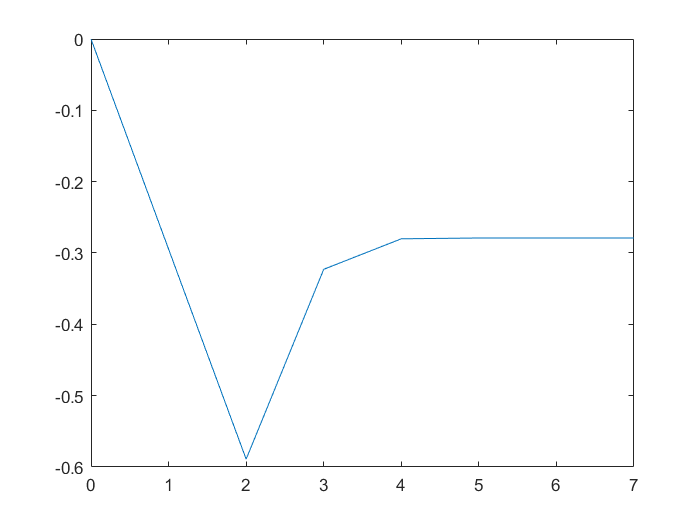

Laguerre(x2, f, df, ddf); % showing real root

** Laguerre **
X: 
   0.6829 + 0.4759i

Error: 
   6.5189e-10

Iterations: 
    13

Plot Iterations/Solution


x_vec =    0.0000 + 0.0000i   6.0502 + 0.0000i   4.0645 + 0.0000i   2.7367 + 0.0000i   1.8544 + 0.0000i   1.2610 + 0.0000i   0.8046 + 0.0000i   0.4877 + 0.6848i   0.6137 + 0.4527i   0.6880 + 0.4742i   0.6829 + 0.4758i   0.6829 + 0.4759i   0.6829 + 0.4759i


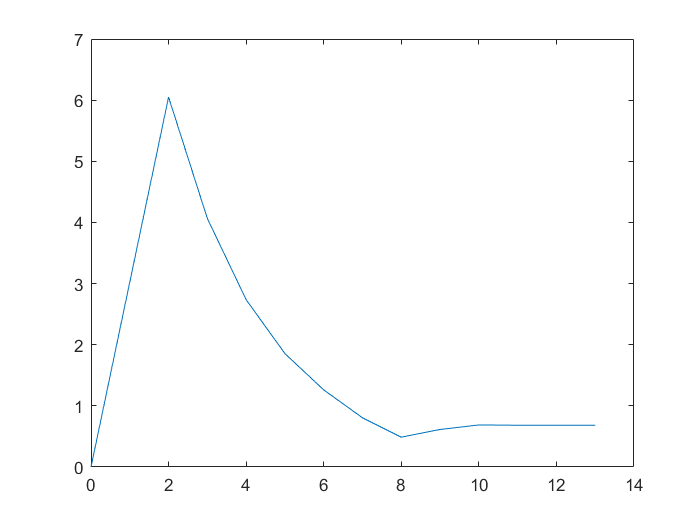

Laguerre(x3, f, df, ddf); % showing complex root

** Laguerre **
X: 
   0.6829 - 0.4759i

Error: 
   1.2413e-16

Iterations: 
    14

Plot Iterations/Solution


x_vec =    0.0000 + 0.0000i   6.0502 + 0.0000i   4.0645 + 0.0000i   2.7367 + 0.0000i   1.8544 + 0.0000i   1.2610 + 0.0000i   0.8046 + 0.0000i   0.4877 - 0.6848i   0.6137 - 0.4527i   0.6880 - 0.4742i   0.6829 - 0.4758i   0.6829 - 0.4759i   0.6829 - 0.4759i   0.6829 - 0.4759i


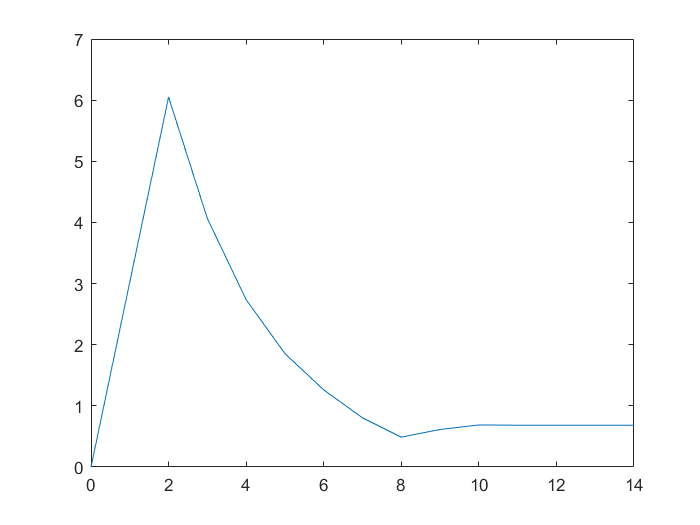

Laguerre_(x3, f, df, ddf); % showing complex root

disp("*************************************");

*************************************
